# Aaron Paul con Miguel

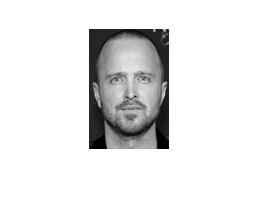

clc
clear
close all
m = 120;
n = 80;
n_images = 5;
images = zeros(m,n,n_images);
image1 = rgb2gray(imresize(imread('fotosw/AaronPaul1.png'),[m,n]));
images(:,:,1) = image1;
imshow(image1);

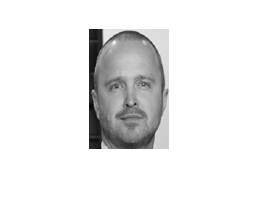


image2 = rgb2gray(imresize(imread('fotosw/AaronPaul2.png'),[m,n]));
images(:,:,2) = image2;
imshow(image2);


image3 = rgb2gray(imresize(imread('fotosw/AaronPaul3.png'),[m,n]));

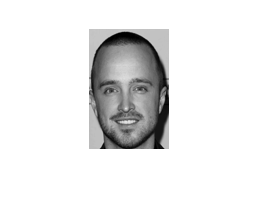

images(:,:,3) = image3;
imshow(image3);


image4 = rgb2gray(imresize(imread('fotosw/AaronPaul4.png'),[m,n]));

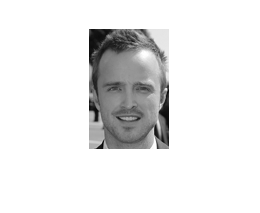

images(:,:,4) = image4;
imshow(image4);

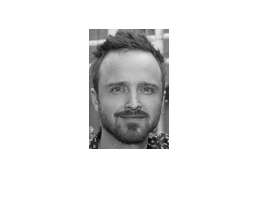


image5 = rgb2gray(imresize(imread('fotosw/AaronPaul5.png'),[m,n]));
images(:,:,5) = image5;
imshow(image5);


fam1 = matriz_a_eq(n_images, m, n, images);
fam1

fam1 =     43    38    38    49    49    38    55    49    38    49    43    49    38    49    55    49    55    49    43    43    43    43    43    43    43    55    55    49    55    49    43    62    62    49    49    29    25    14    12    11    13    14    16    19    26    31    38    49    55    49
    19    16    13    10     6     4     3     7    15    20    23    20    18    84   228   251   253   252   252   253   252   252   251   251   251   250   251   250   250   251   250   250   250   250   252   254   254   255   255   255   255   255   255   254   254   252   251   251   249   249
   234   234   234   234   238   244   244   238   238   244   234   244   244   238   244   244   244   234   238   234   238   234   234   234   234   234   234   234   234   238   244   246   246   238   234   238   238   234   234   234   234   238   238   238   234   238   238   234   234   234
    38    24     9     5     5     8    15    18    20    23    24    25    19    14     9

A1 = transpose(fam1);

C1 = A1 * fam1;

[V1,D1] = eigs(C1,20);

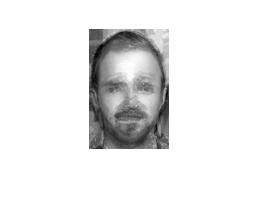

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

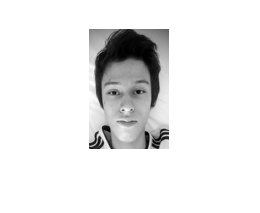

test_img = rgb2gray(imresize(imread('fotos/luis.jpg'),[m,n]));
imshow(test_img,[])

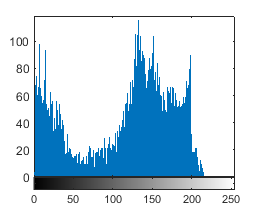

[counts,binLocations] = imhist(test_img);
imhist(test_img);

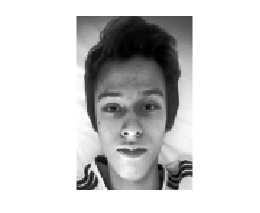

[s,image_t] = equalization(test_img,counts);

imshow(image_t)

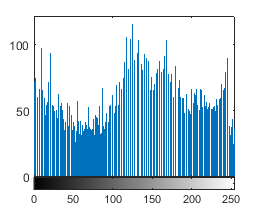

imhist(image_t)

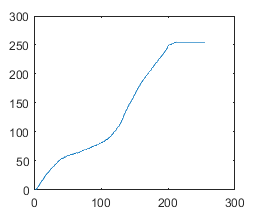

counts_s = imhist(image_t);
plot(s)

test_v = reshape(transpose(double(image_t)),[1,m*n]);

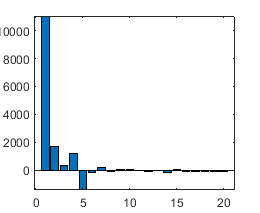

p = test_v * V1;
bar(p)

X = V1 * transpose(p);

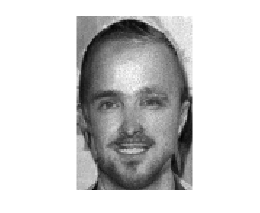

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

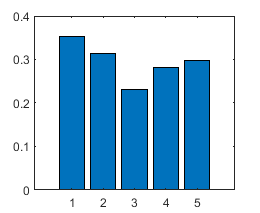

errors1 = calcular_error(fam1, V1, test_v);
bar(errors1)

mean(errors1)

ans = 0.2958